load('EOS_52Images_30pointsPoly.mat');

mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
k=2.5;
Ktlist=Ktlist/k;
Ptlist=Ptlist*k;

[ KappaTildeT, PTildeT, ~, ~ ] = VirialUnitarity(  2, 7,2000 , 3 );

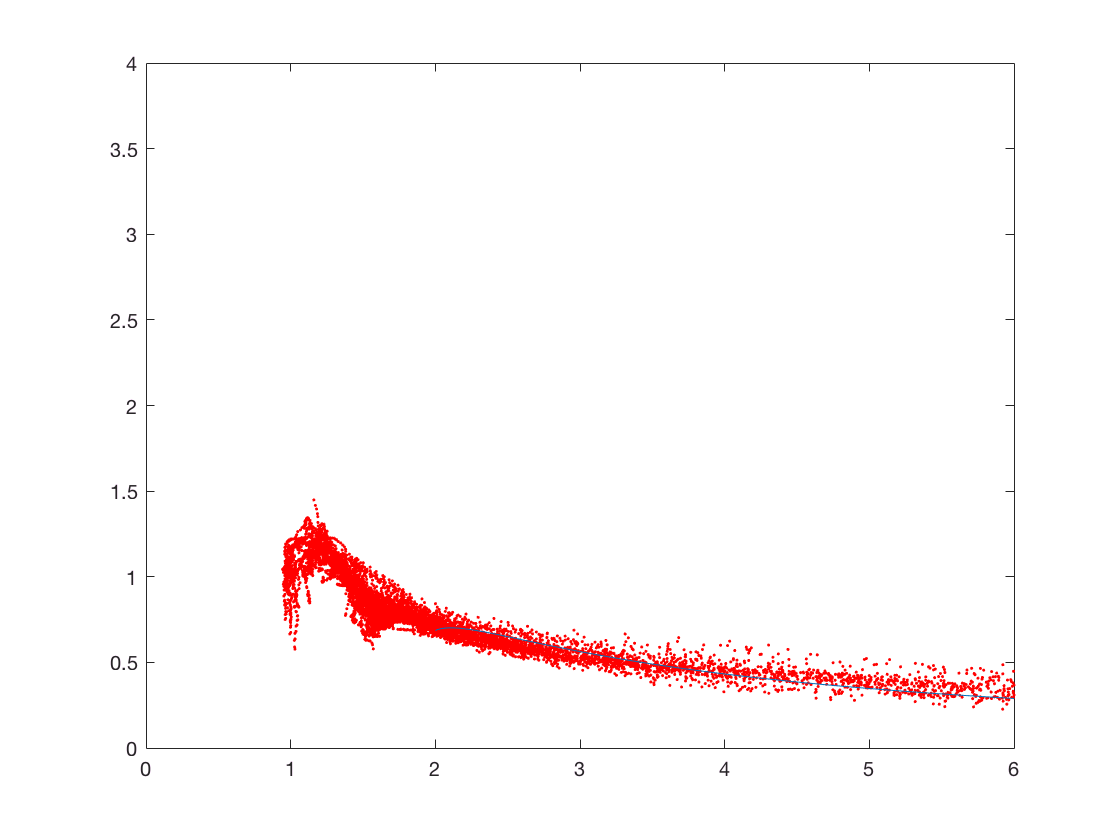

plot(Ptlist,Ktlist,'r.');
hold on
plot(PTildeT,KappaTildeT);
hold off
xlim([0,6]);ylim([0,4]);



PtBinMin=0;
PtBinMax=7;
dPt=0.02;
Ptbin=PtBinMin:dPt:PtBinMax;
Nbin=size(Ptbin,2);
M=length(Ktlist);
KtBinList=cell(1,Nbin);
KtMean=zeros(1,Nbin);
KtStd=zeros(1,Nbin);
for i=1:Nbin
    KtBinList{i}=[];
end

for i=1:M
    K=round((Ptlist(i)-PtBinMin)/dPt+1);
    if K<=Nbin && K>=1
        temp=KtBinList{K};
        KtBinList{K}=[temp,Ktlist(i)];
    end
end

for i=1:Nbin
    KtMean(i)=mean(KtBinList{i});
    KtStd(i)=std(KtBinList{i})/sqrt(length(KtBinList{i}));
end

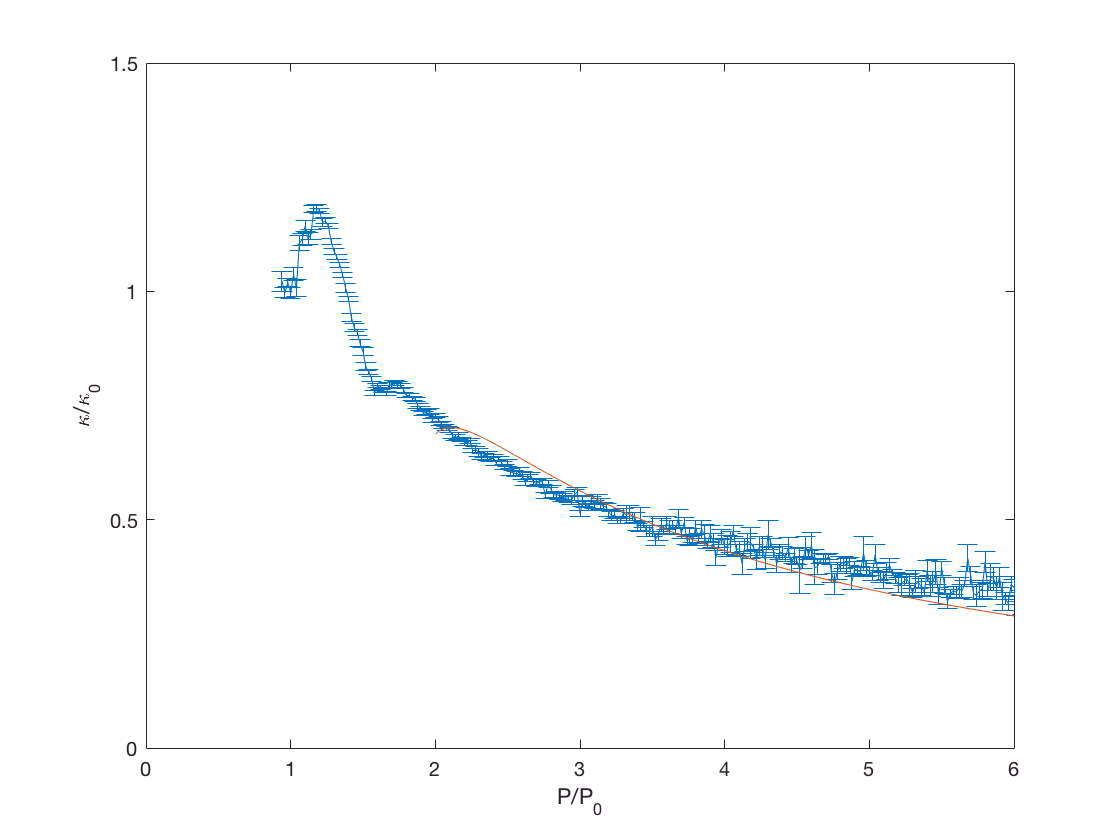

errorbar(Ptbin,KtMean,KtStd)
hold on
plot(PTildeT,KappaTildeT);
hold off
xlim([0,6]);ylim([0,1.5]);
xlabel('P/P_0');ylabel('\kappa/\kappa_0');